# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:**

# Tema 4. Ejercicio 2. Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de los contornos exteriores de los objetos de una imagen y reconstruirlos utilizando únicamente una parte de sus componentes de baja frecuencia, analizando cómo influye el número de componentes utilizadas en la aproximación obtenida.

Las funciones proporcionadas centran internamente la transformada, de forma que al reducir el número de componentes se conservan las componentes de baja frecuencia y se eliminan progresivamente las de mayor frecuencia.

Se pide: 

- Complete el paso 4, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier del contorno de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Consulte los comentarios de la función para realizar la reconstrucción utilizando aproximadamente el **10 %** del total de componentes. Dibuje cada contorno reconstruido sobre la figura original utilizando `hold on` y compruebe visualmente cómo se ajusta al contorno original.

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 5**%** del total**.**

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 2**%** del total

- Compare los resultados obtenidos con los tres porcentajes. Explique qué ocurre al reducir el número de componentes y relacione el resultado con la información representada por las componentes de baja y alta frecuencia.

Step 1) Read Image

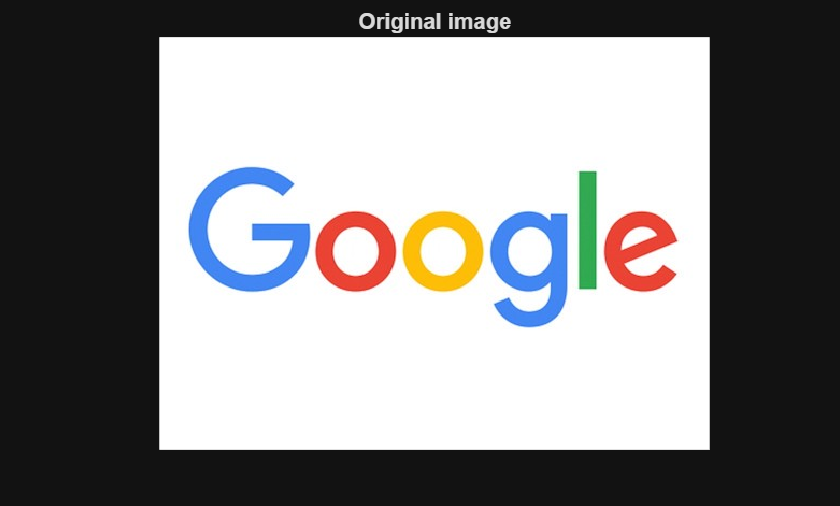

    close all
    clear all

    imgOriginal = imread('google.jpg');
    figure;
    imshow(imgOriginal);
    title('Original image');

Step 2) Threshold the Image

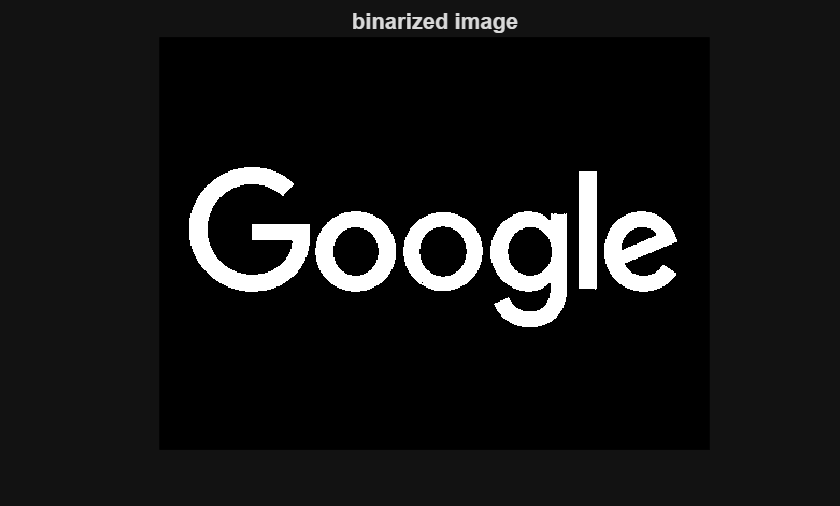

    if size(imgOriginal,3) == 3
        imgOriginal = rgb2gray(imgOriginal); 
    end
    imgBW = imbinarize(imgOriginal);
    imgBW = imcomplement(imgBW);
    
    figure;
    imshow(imgBW);
    title('binarized image');

Step 3) Find the external Boundaries

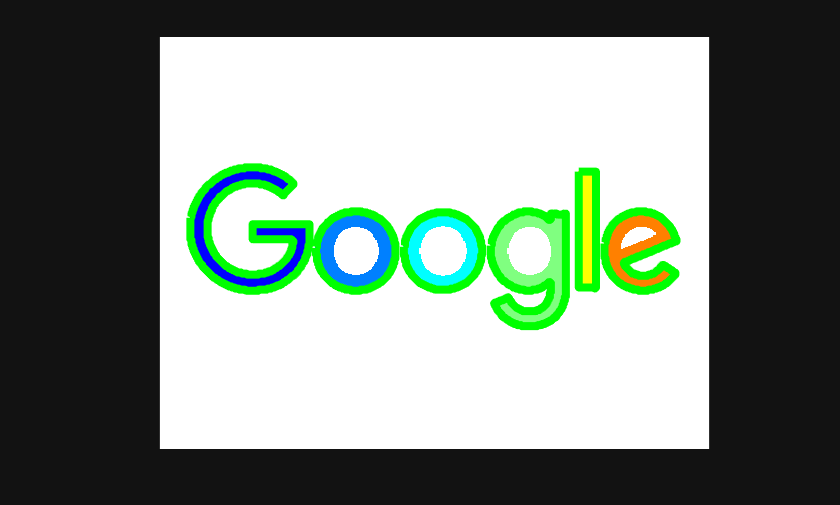

    % Se cogen los contornos exteriores de las letras de "Google".
    % Como se usa 'noholes', solo se reconstruye el contorno exterior de cada letra. P.ej. el agujero de las "o" no se procesa.
    [B,L] = bwboundaries(imgBW,'noholes');
    figure
    imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
    hold on
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
    end  

Step 4)  Fourier transform 

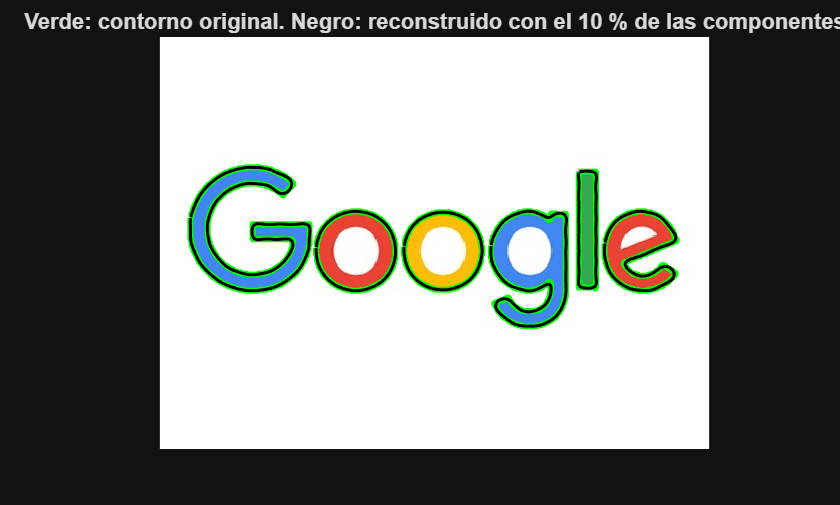

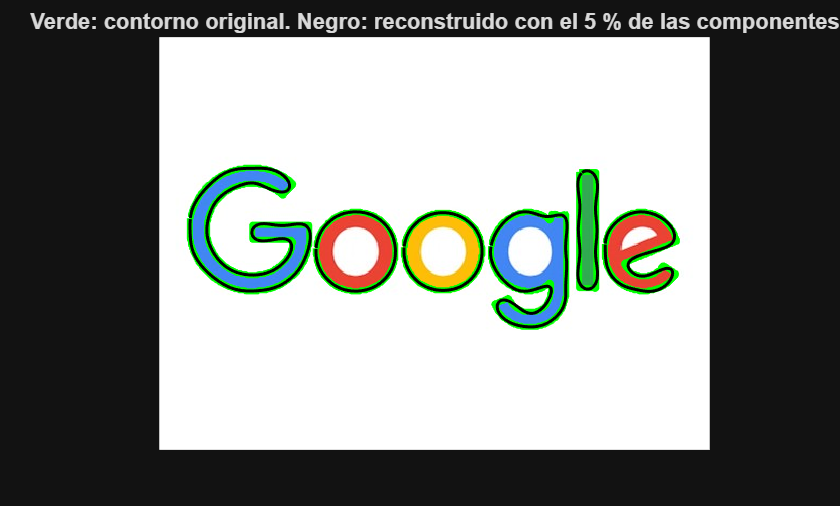

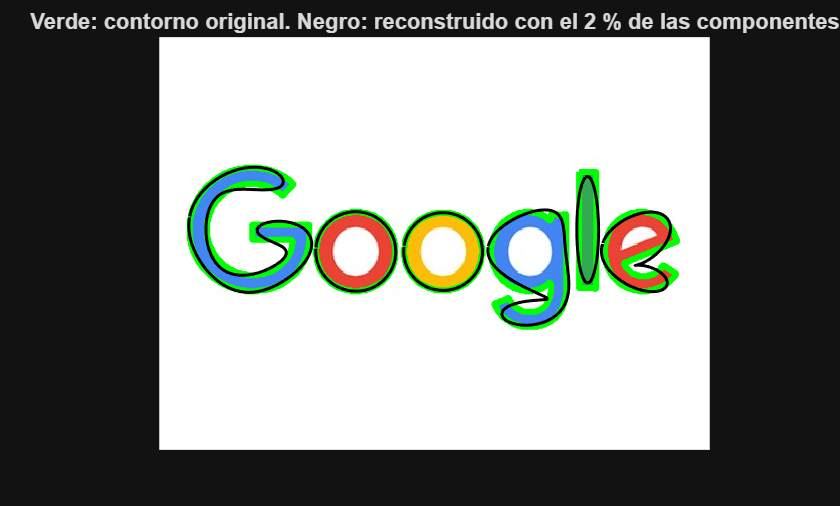

% Porcentajes de componentes que vamos a probar: 10%, 5% y 2%
porcentajes = [0.10 0.05 0.02];

% En el paso 2, imgOriginal se convirtió a grises, así que vuelvo a leer la imagen en color para dibujar encima
imgColor = imread('google.jpg');

numObj = length(B); % número de objetos (letras)
tablaComp = zeros(numObj, 4); % para guardar cuántas componentes se usan: columna 1 = total N, 2 = 10%, 3 = 5%, 4 = 2%

% Bucle externo: una figura por cada porcentaje
for p = 1:length(porcentajes)
    porcentaje = porcentajes(p);

    figure
    imshow(imgColor)
    hold on

    % Bucle interno: para cada letra
    for k = 1:numObj
        boundary = B{k}; % contorno original [fila, columna]

        % A cada contorno se le calcula la transformada de Fourier
        % Apartado 1: transformada de Fourier del contorno
        z = fourier_transform(boundary); % N componentes (números complejos)
        N = length(z); % número total de componentes

        % Apartado 2: nº de componentes que conservamos
        nd = round(porcentaje * N);

        % Se reconstruye el contorno con solo una parte de las componentes: el 10%, el 5% y el 2%.
        % Transformada inversa usando solo las nd de baja frecuencia
        s = fourier_inv_transform(z, nd); % contorno reconstruido [fila, columna]

        % Dibujo del original en verde (grueso) y el reconstruido en negro encima. 
        % Igual que en el ejercicio 1: columna 2 = x, columna 1 = y
        plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 3)
        plot(s(:,2), s(:,1), 'k', 'LineWidth', 1.5)

        % Guardamos el número de componentes para la tabla
        tablaComp(k, 1) = N;
        tablaComp(k, p + 1) = nd;
    end

    hold off
    title(['Verde: contorno original. Negro: reconstruido con el ', num2str(porcentaje*100), ' % de las componentes'])
end


% Tabla con el nº de componentes usadas por cada objeto
tablaComponentes = array2table([(1:numObj)' tablaComp], 'VariableNames', {'Objeto', 'N_total', 'Comp_10', 'Comp_5', 'Comp_2'})

tablaComponentes = 6×5 table
    Objeto    N_total    Comp_10    Comp_5    Comp_2
    ______    _______    _______    ______    ______

      1         602        60         30        12  
      2         212        21         11         4  
      3         208        21         10         4  
      4         392        39         20         8  
      5         250        25         13         5  
      6         278        28         14         6  

	Get insights using Copilot


Al reducir el número de componentes de Fourier usadas en la reconstrucción, el contorno obtenido se va suavizando y pierde detalle, pero conserva la forma global del objeto. Con el 10% de las componentes, la reconstrucción es prácticamente idéntica al contorno original. Con el 5% las esquinas empiezan a redondearse y aparecen pequeñas ondulaciones en los tramos rectos. Con el 2% se pierden los detalles finos: la "l" se vuelve ondulada, la barra de la G se desdibuja y la cola de la "g" y el entrante de la "e" se deforman. Aun así, cada letra sigue siendo bastante reconocible.

Esto se debe a que las componentes de baja frecuencia describen la forma global del contorno, mientras que las de alta frecuencia representan los detalles más finos: esquinas, cambios bruscos de dirección y tramos rectos. Las funciones usadas conservan las componentes centrales de la transformada (baja frecuencia) y anulan las de los extremos (alta frecuencia), por lo que al reducir el porcentaje se eliminan precisamente los detalles. Las ondulaciones cerca de las esquinas aparecen porque un cambio brusco de dirección no se puede representar con pocas componentes de baja frecuencia.

El efecto depende de la forma del objeto. Las "o", casi circulares, se reconstruyen muy bien incluso con el 2 % (unas 5–6 componentes), porque un círculo se describe con una sola componente de frecuencia además de F(0), que fija su posición. Las letras con esquinas y tramos rectos, como la "l", la "G" o la "e", se degradan antes porque necesitan más componentes de alta frecuencia. Para formas sencillas basta un número reducido de componentes para obtener una buena aproximación, lo que permite representar el contorno con muchos menos datos y una pérdida mínima.